% List of specific image numbers
imageNumbers = [33, 38, 41, 46, 51, 58, 76, 89, 90, 92];

% Base directories for the images and ground truth
baseDirImages = 'F:/Semester 6/Pengolahan Citra Biomedika/Tubes/Images/testing/';
baseDirGT = 'F:/Semester 6/Pengolahan Citra Biomedika/Tubes/GT/Testing/';

% Output directory for the overlay images
outputDir = 'F:/Semester 6/Pengolahan Citra Biomedika/Tubes/OverlayOutput/';
if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end

% Output directory for the histograms
histOutputDir = fullfile(outputDir, 'Combined OC Histograms');
if ~exist(histOutputDir, 'dir')
    mkdir(histOutputDir);
end

% Initialize arrays to store the maximum frequencies for each intensity bin
maxHistRed = zeros(256, 1);
maxHistGreen = zeros(256, 1);
maxHistBlue = zeros(256, 1);

for i = 1:length(imageNumbers)
    % Get the current image number
    imageNumber = imageNumbers(i);
    
    % Generate filenames for the images
    imageFile = fullfile(baseDirImages, sprintf('drishtiGS_%03d.png', imageNumber));
    gtFile = fullfile(baseDirGT, sprintf('drishtiGS_%03d', imageNumber), sprintf('drishtiGS_%03d_CupAvgBoundary_OC_img.png', imageNumber));
    
    % Debug: Print file paths
    fprintf('Processing image: %s\n', imageFile);
    fprintf('Processing GT: %s\n', gtFile);
    
    % Check if the files exist
    if isfile(imageFile) && isfile(gtFile)
        % Read the images
        img = imread(imageFile);
        gtImg = imread(gtFile);
        
        % Debug: Print success message for reading files
        fprintf('Successfully read image and GT for %03d\n', imageNumber);
        
        % Convert the ground truth image to a logical mask
        gtMask = logical(gtImg);
        
        % Convert the main image to RGB if it's grayscale
        if size(img, 3) == 1
            img = repmat(img, [1, 1, 3]);
        end
        
        % Create a masked version of the original image
        overlayImg = img;
        for channel = 1:3
            channelData = img(:,:,channel);
            channelData(~gtMask) = 0;
            overlayImg(:,:,channel) = channelData;
        end
        
        % Save the overlay image to the output directory
        outputFileName = fullfile(outputDir, sprintf('overlay_%03d.png', imageNumber));
        imwrite(overlayImg, outputFileName);
        
        % Debug: Print success message for saving overlay
        fprintf('Saved overlay image: %s\n', outputFileName);
        
        % Generate histograms for the red, green, and blue channels and update maximum frequencies
        for channel = 1:3
            channelData = overlayImg(:,:,channel);
            histValues = imhist(channelData(gtMask));
            
            switch channel
                case 1
                    maxHistRed = max(maxHistRed, histValues);
                case 2
                    maxHistGreen = max(maxHistGreen, histValues);
                case 3
                    maxHistBlue = max(maxHistBlue, histValues);
            end
        end
    else
        fprintf('Files not found for image number: %03d\n', imageNumber);
    end
end

Processing image: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\Images\testing\drishtiGS_033.png


Processing GT: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\GT\Testing\drishtiGS_033\drishtiGS_033_CupAvgBoundary_OC_img.png


Successfully read image and GT for 033


Saved overlay image: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\OverlayOutput\overlay_033.png


Processing image: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\Images\testing\drishtiGS_038.png


Processing GT: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\GT\Testing\drishtiGS_038\drishtiGS_038_CupAvgBoundary_OC_img.png


Successfully read image and GT for 038


Saved overlay image: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\OverlayOutput\overlay_038.png


Processing image: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\Images\testing\drishtiGS_041.png


Processing GT: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\GT\Testing\drishtiGS_041\drishtiGS_041_CupAvgBoundary_OC_img.png


Successfully read image and GT for 041


Saved overlay image: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\OverlayOutput\overlay_041.png


Processing image: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\Images\testing\drishtiGS_046.png


Processing GT: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\GT\Testing\drishtiGS_046\drishtiGS_046_CupAvgBoundary_OC_img.png


Successfully read image and GT for 046


Saved overlay image: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\OverlayOutput\overlay_046.png


Processing image: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\Images\testing\drishtiGS_051.png


Processing GT: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\GT\Testing\drishtiGS_051\drishtiGS_051_CupAvgBoundary_OC_img.png


Successfully read image and GT for 051


Saved overlay image: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\OverlayOutput\overlay_051.png


Processing image: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\Images\testing\drishtiGS_058.png


Processing GT: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\GT\Testing\drishtiGS_058\drishtiGS_058_CupAvgBoundary_OC_img.png


Successfully read image and GT for 058


Saved overlay image: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\OverlayOutput\overlay_058.png


Processing image: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\Images\testing\drishtiGS_076.png


Processing GT: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\GT\Testing\drishtiGS_076\drishtiGS_076_CupAvgBoundary_OC_img.png


Successfully read image and GT for 076


Saved overlay image: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\OverlayOutput\overlay_076.png


Processing image: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\Images\testing\drishtiGS_089.png


Processing GT: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\GT\Testing\drishtiGS_089\drishtiGS_089_CupAvgBoundary_OC_img.png


Successfully read image and GT for 089


Saved overlay image: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\OverlayOutput\overlay_089.png


Processing image: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\Images\testing\drishtiGS_090.png


Processing GT: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\GT\Testing\drishtiGS_090\drishtiGS_090_CupAvgBoundary_OC_img.png


Successfully read image and GT for 090


Saved overlay image: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\OverlayOutput\overlay_090.png


Processing image: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\Images\testing\drishtiGS_092.png


Processing GT: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\GT\Testing\drishtiGS_092\drishtiGS_092_CupAvgBoundary_OC_img.png


Successfully read image and GT for 092


Saved overlay image: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\OverlayOutput\overlay_092.png


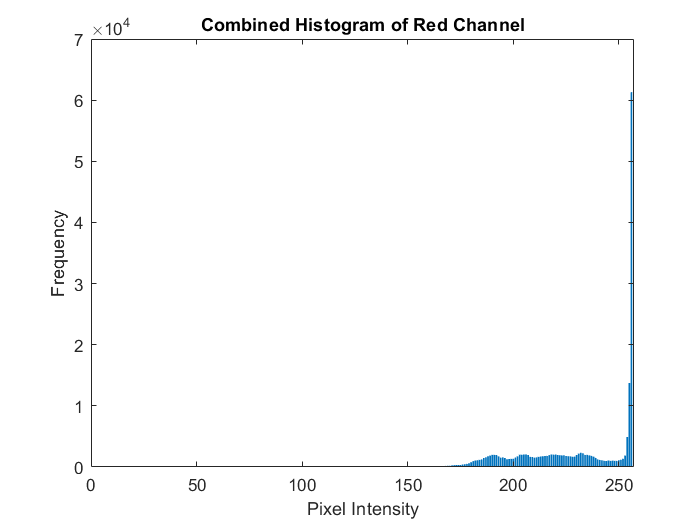


% Save the combined histograms as images
figure;
bar(maxHistRed);
title('Combined Histogram of Red Channel');
xlabel('Pixel Intensity');
ylabel('Frequency');
saveas(gcf, fullfile(histOutputDir, 'combined_hist_Red.png'));

close;

figure;
bar(maxHistGreen);
title('Combined Histogram of Green Channel');
xlabel('Pixel Intensity');
ylabel('Frequency');
saveas(gcf, fullfile(histOutputDir, 'combined_hist_Green.png'));
close;

figure;
bar(maxHistBlue);
title('Combined Histogram of Blue Channel');
xlabel('Pixel Intensity');
ylabel('Frequency');
saveas(gcf, fullfile(histOutputDir, 'combined_hist_Blue.png'));
close;

% Debug: Print success message for saving combined histograms
fprintf('Saved combined histograms in: %s\n', histOutputDir);

Saved combined histograms in: F:\Semester 6\Pengolahan Citra Biomedika\Tubes\OverlayOutput\Combined OC Histograms
